Linear filtering. Gaussian noise.

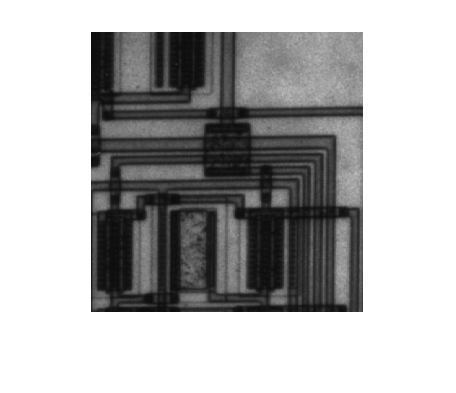

clear all;
close all;
clc;

gene_filters;
img = imread('circuit.tif');
imshow(img)

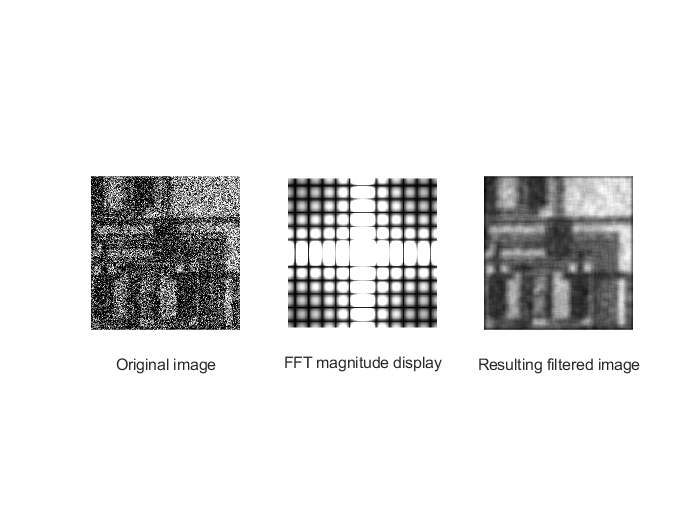

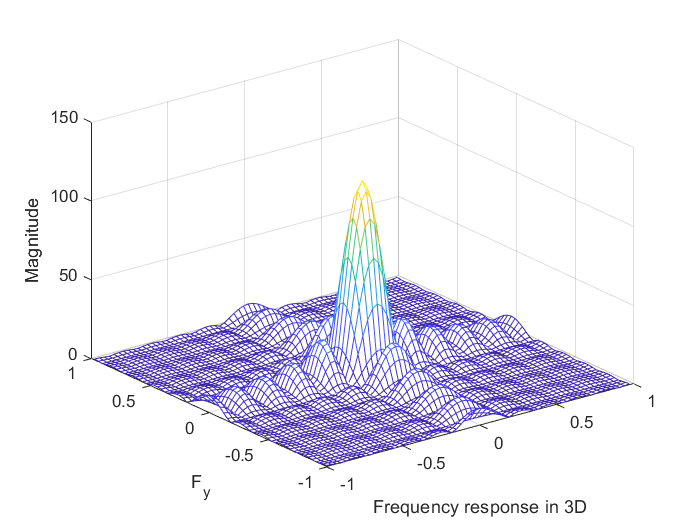

img_noise = imnoise(img, 'gaussian', 0, 0.1);
% img_out = Analyse_Filter_test(img_noise, fmean3);
img_out = Analyse_Filter_test(img_noise, fmean11);

% img_out = Analyse_Filter_test(img_noise, fgaussian5_1);

Nonlinear filter, median filtering. Pepper & Salt noise.

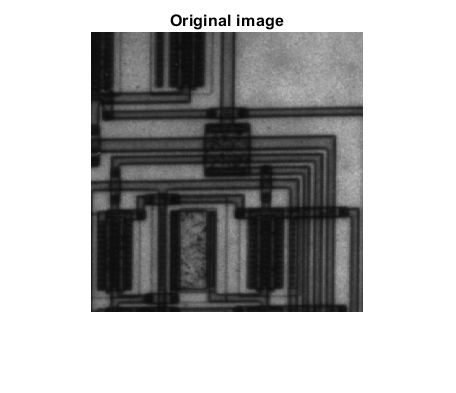

clear all;
close all;
clc;

gene_filters;
img = imread('circuit.tif');
imshow(img);
title('Original image');

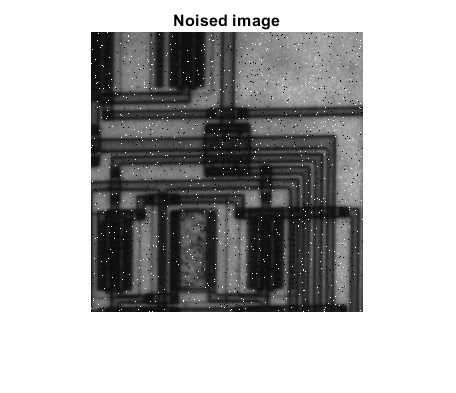

img_noise_2 = imnoise(img,'salt & pepper',0.02);
imshow(img_noise_2);
title('Noised image');

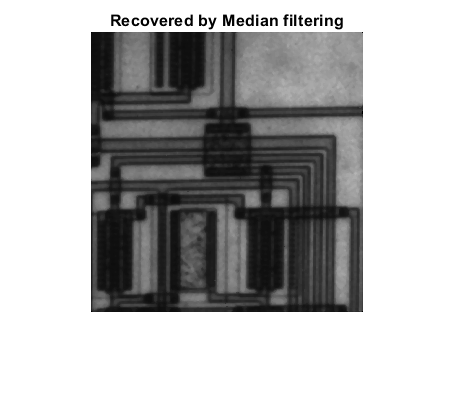

img_out_2 = medfilt2(img_noise_2);
imshow(img_out_2);
title('Recovered by Median filtering');

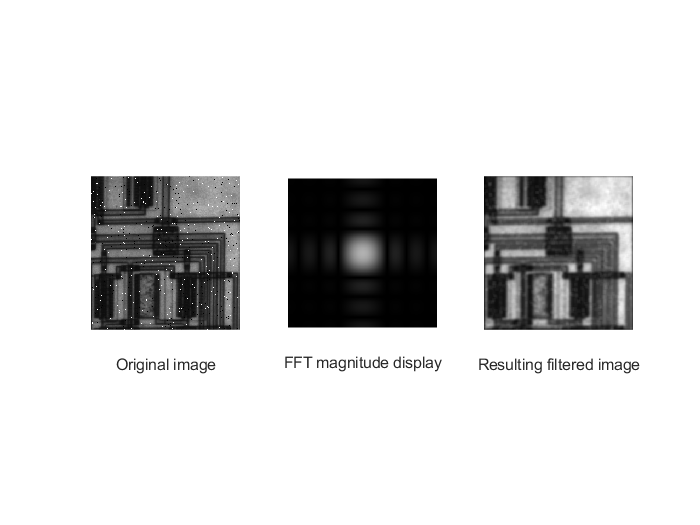

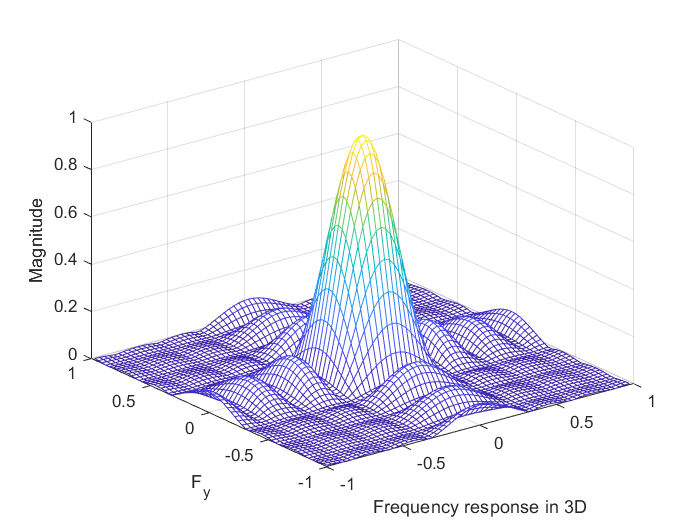

% By using Gaussian filter to try to filter out impulse noise, the image
% will be bulrred.
img_out_3 = Analyse_Filter_test(img_noise_2, fgaussian7_3);

% img_out_3 = Analyse_Filter_test(img_noise_2, fmean3);

Log-transform and Speckle noise. 

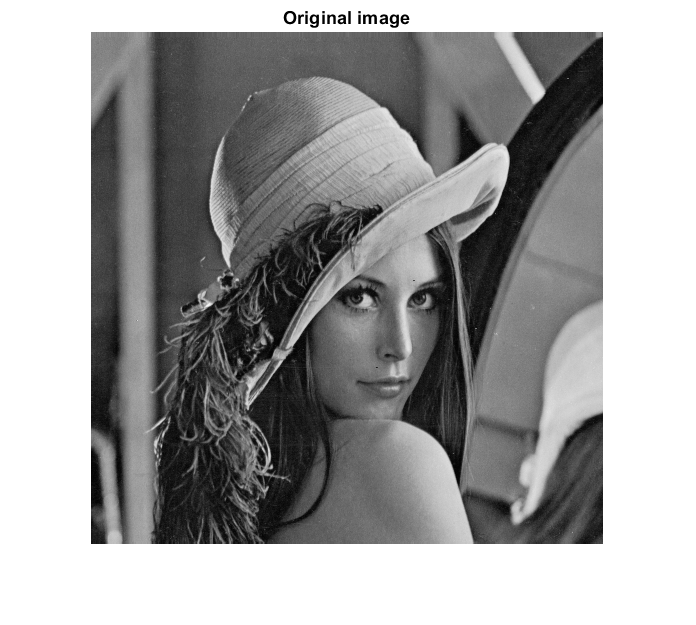

clear all;
close all;
clc;

gene_filters;
img = imread('lena.jpg');
imshow(img);
title('Original image');

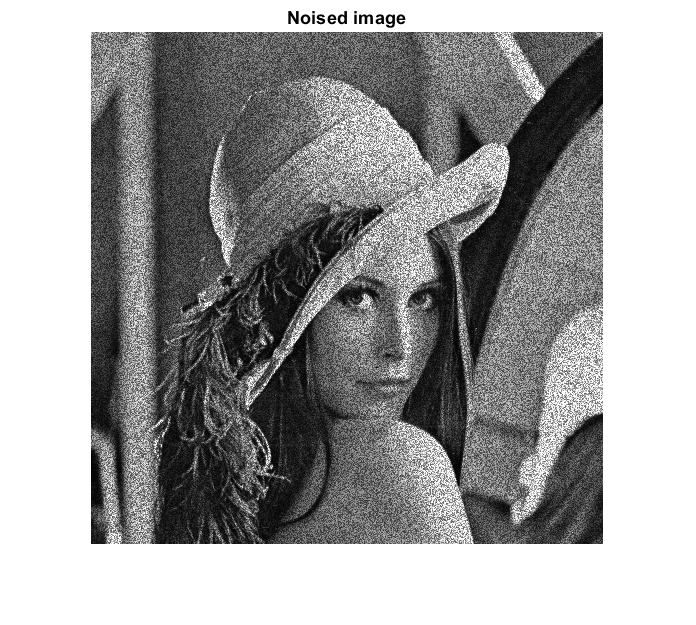

img_noise_3 = imnoise(img,'speckle',0.1);
imshow(img_noise_3);
title('Noised image');

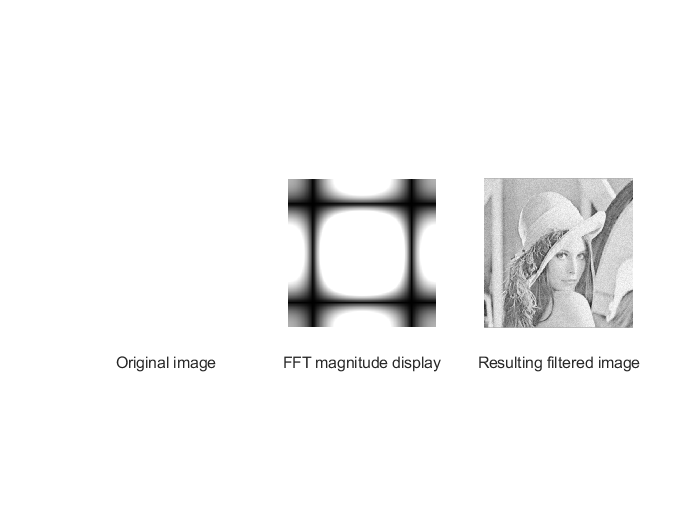

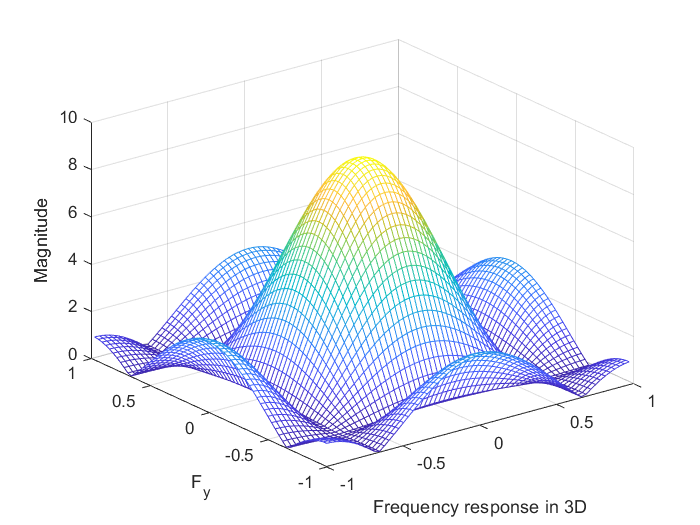

img_noise_log_version = 2.*log(double(img_noise_3) + 1);
% img_noise_log_version = log(im2double(img_noise_3));
img_log_after_filter = Analyse_Filter_test(img_noise_log_version, fmean3);

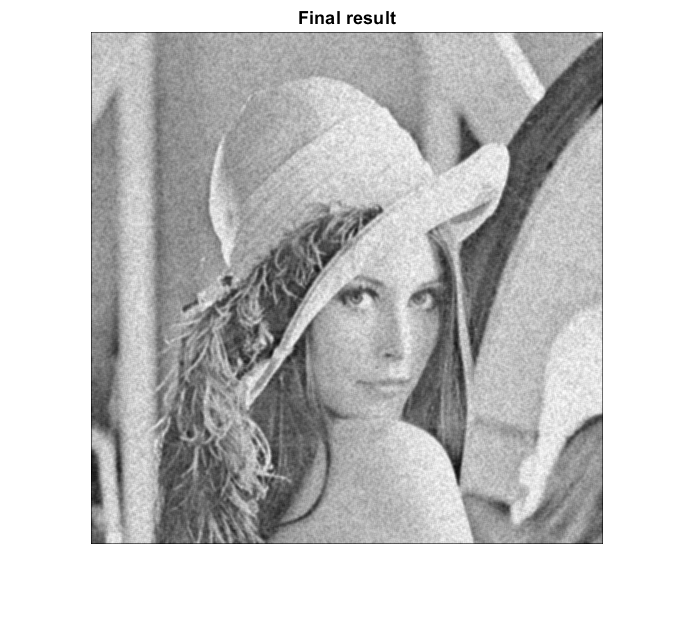

img_final_after_filter = exp(img_log_after_filter);
% img_final_after_filter_normalised = (img_final_after_filter - min(img_final_after_filter(:))) / (max(img_final_after_filter(:)) - min(img_final_after_filter(:)));
transform_final_img = 255.*(mat2gray(img_final_after_filter));
imshow(uint8(transform_final_img));
% imshow(mat2gray(img_final_after_filter))
title('Final result');